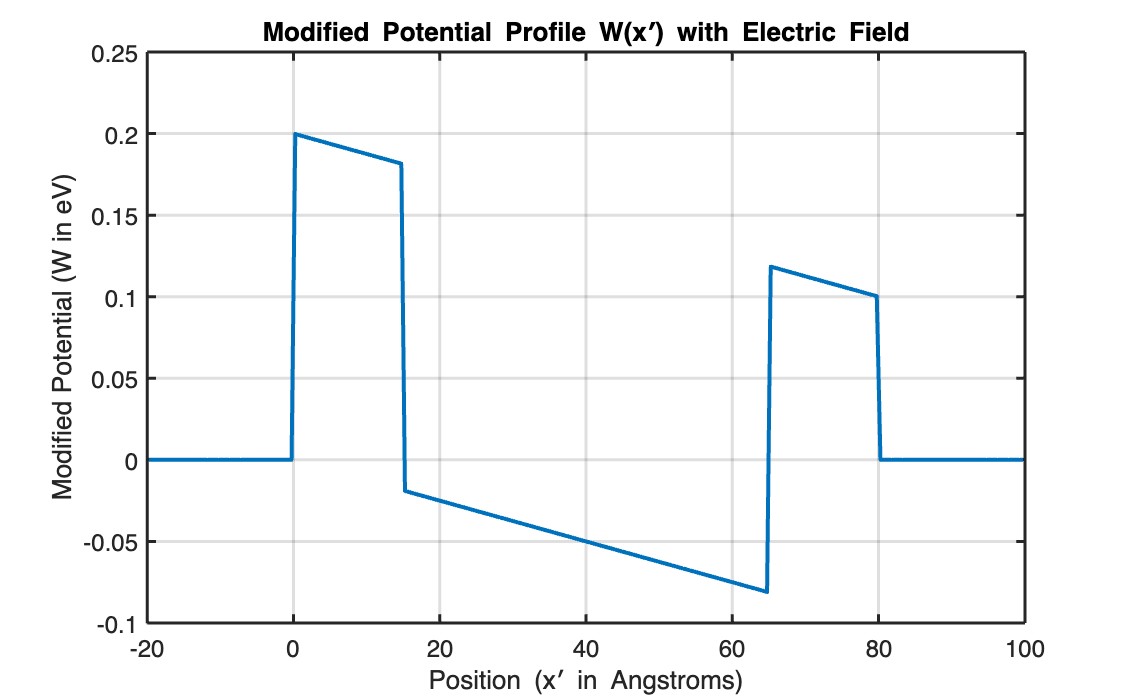

Lower energy bound (Ea) = 0.000000 eV
Upper energy bound (Eb) = 3.809982 eV


mystartdefaults
part_2

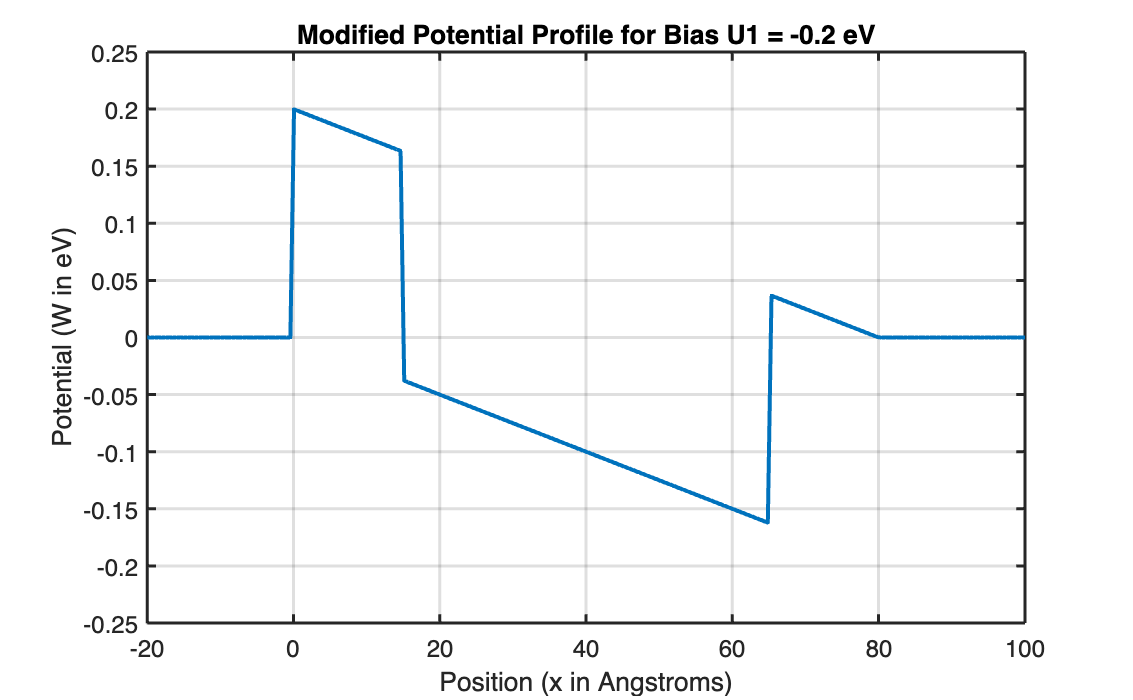

% Define the x array
x = linspace(x_min, x_max, n);
% Bias values
U1_values = [-0.2, 0.2];

% Initialize arrays to store the modified potentials
W_minus_02 = zeros(1, n);
W_plus_02 = zeros(1, n);

% Loop over the bias values
for idx = 1:length(U1_values)
    U1 = U1_values(idx);

    % Potential barrier
    U = zeros(1, n);
    U(x > 0 & x <= 15) = 0.2;
    U(x >= 65 & x <= 80) = 0.2;

    % Calculate the electric field and the modified potential
    E = -U1 / (x_prime_max - x_prime_min);
    W = U;
    W(x > x_prime_min & x < x_prime_max) = U(x > x_prime_min & x < x_prime_max) - E * x(x > x_prime_min & x < x_prime_max);

    % Store the modified potential for each bias
    if U1 == -0.2
        W_minus_02 = W;
    elseif U1 == 0.2
        W_plus_02 = W;
    end
end

% Plot the modified potential profile for U1 = -0.2 eV
figure;
plot(x, W_minus_02, 'LineWidth', 2);
title('Modified Potential Profile for Bias U1 = -0.2 eV');
xlabel('Position (x in Angstroms)');
ylabel('Potential (W in eV)');
ylim([-0.25 0.25]);
grid on;

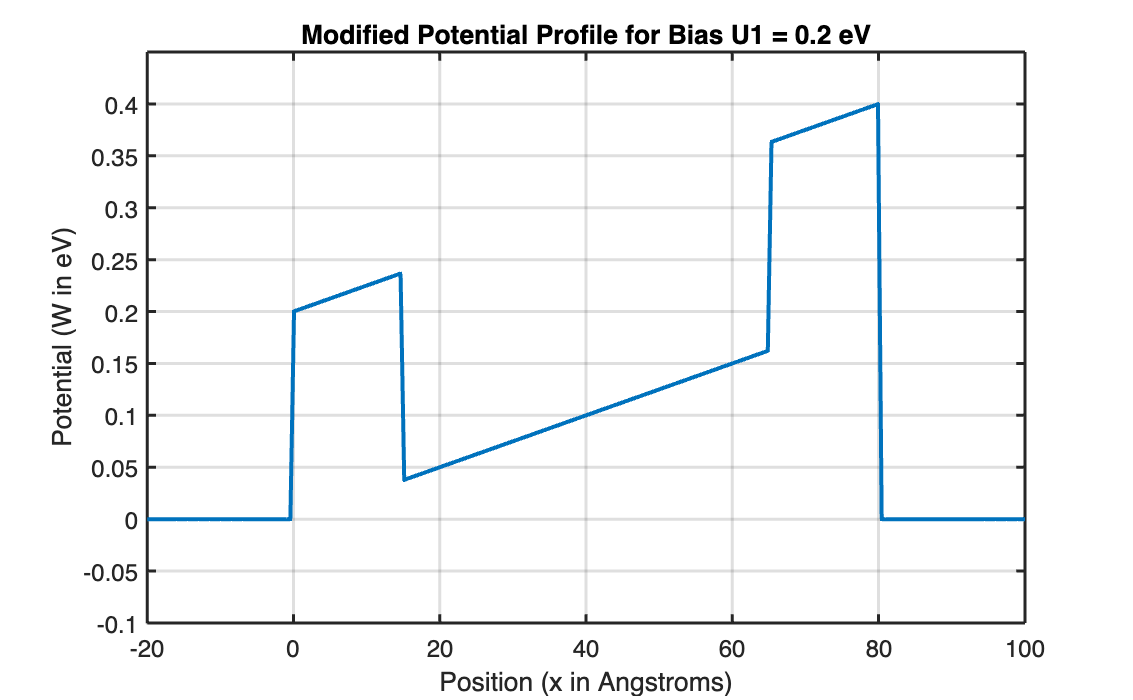


% Plot the modified potential profile for U1 = 0.2 eV
figure;
plot(x, W_plus_02, 'LineWidth', 2);
title('Modified Potential Profile for Bias U1 = 0.2 eV');
xlabel('Position (x in Angstroms)');
ylabel('Potential (W in eV)');
ylim([-0.1 0.45]);
grid on;